A = readtable("Lab2_training.txt"); 
A = A{:,:}

A =    -0.6508    0.1097    4.0009         0
   -1.4492    0.8896    4.4005         0
    2.0850    0.6876   12.0710         0
    0.2626    1.1476    7.7985    1.0000
    0.6418    1.0234    7.0427    1.0000
    0.2569    0.6730    8.3265         0
    1.1155    0.6043    7.4446    1.0000
    0.0914    0.3399    7.0677         0
    0.0121    0.5256    4.6316    1.0000
   -0.0429    0.4660    5.4323    1.0000


A = A(randperm(size(A, 1)), :);

% nie ma danych testowych
X_train = A(:,1:3)

X_train =     2.0149    0.6192   10.9263
    0.2013    1.0014    6.5489
    1.1155    0.6043    7.4446
    2.0850    0.6876   12.0710
    0.6418    1.0234    7.0427
    0.5307    0.1285    5.6883
   -0.7970    0.8795    3.8762
    0.4839    0.4851    7.4850
    0.3957    0.1076    5.6623
   -0.1013    0.5989    7.1812


y_train = A(:, 4)

y_train =      0
     1
     1
     0
     1
     1
     1
     0
     0
     0


nets = cell(5,1)

nets = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for i = 1:5
    nets{i} = train_net(X_train, y_train)
end

XY =     2.0149    0.6192   10.9263         0
    0.2013    1.0014    6.5489    1.0000
    1.1155    0.6043    7.4446    1.0000
    2.0850    0.6876   12.0710         0
    0.6418    1.0234    7.0427    1.0000
    0.5307    0.1285    5.6883    1.0000
   -0.7970    0.8795    3.8762    1.0000
    0.4839    0.4851    7.4850         0
    0.3957    0.1076    5.6623         0
   -0.1013    0.5989    7.1812         0


nets = 5×1 cell array
    {1×1 network}
    {0×0 double }
    {0×0 double }
    {0×0 double }
    {0×0 double }


XY =     2.0149    0.6192   10.9263         0
    0.2013    1.0014    6.5489    1.0000
    1.1155    0.6043    7.4446    1.0000
    2.0850    0.6876   12.0710         0
    0.6418    1.0234    7.0427    1.0000
    0.5307    0.1285    5.6883    1.0000
   -0.7970    0.8795    3.8762    1.0000
    0.4839    0.4851    7.4850         0
    0.3957    0.1076    5.6623         0
   -0.1013    0.5989    7.1812         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {0×0 double }
    {0×0 double }
    {0×0 double }


XY =     2.0149    0.6192   10.9263         0
    0.2013    1.0014    6.5489    1.0000
    1.1155    0.6043    7.4446    1.0000
    2.0850    0.6876   12.0710         0
    0.6418    1.0234    7.0427    1.0000
    0.5307    0.1285    5.6883    1.0000
   -0.7970    0.8795    3.8762    1.0000
    0.4839    0.4851    7.4850         0
    0.3957    0.1076    5.6623         0
   -0.1013    0.5989    7.1812         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {0×0 double }
    {0×0 double }


XY =     2.0149    0.6192   10.9263         0
    0.2013    1.0014    6.5489    1.0000
    1.1155    0.6043    7.4446    1.0000
    2.0850    0.6876   12.0710         0
    0.6418    1.0234    7.0427    1.0000
    0.5307    0.1285    5.6883    1.0000
   -0.7970    0.8795    3.8762    1.0000
    0.4839    0.4851    7.4850         0
    0.3957    0.1076    5.6623         0
   -0.1013    0.5989    7.1812         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {0×0 double }


XY =     2.0149    0.6192   10.9263         0
    0.2013    1.0014    6.5489    1.0000
    1.1155    0.6043    7.4446    1.0000
    2.0850    0.6876   12.0710         0
    0.6418    1.0234    7.0427    1.0000
    0.5307    0.1285    5.6883    1.0000
   -0.7970    0.8795    3.8762    1.0000
    0.4839    0.4851    7.4850         0
    0.3957    0.1076    5.6623         0
   -0.1013    0.5989    7.1812         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {1×1 network}


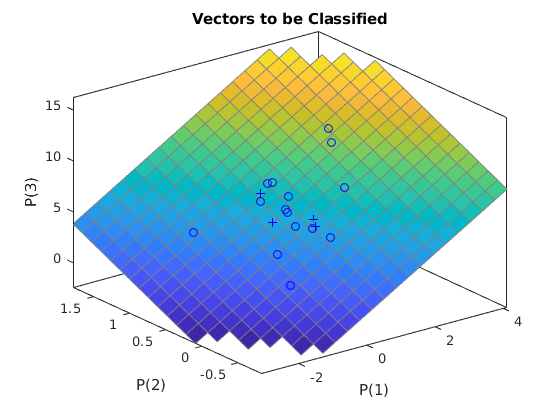

hiper_plot(nets{1}, X_train, y_train);

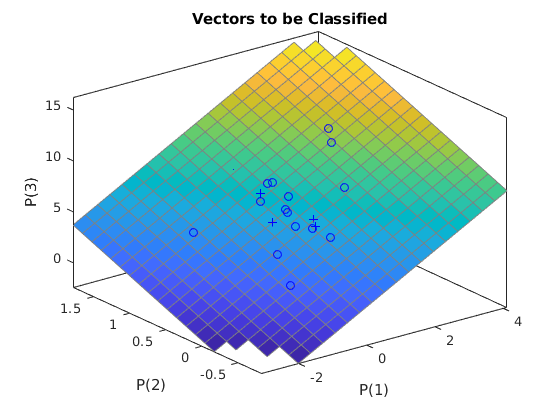

hiper_plot(nets{2}, X_train, y_train);

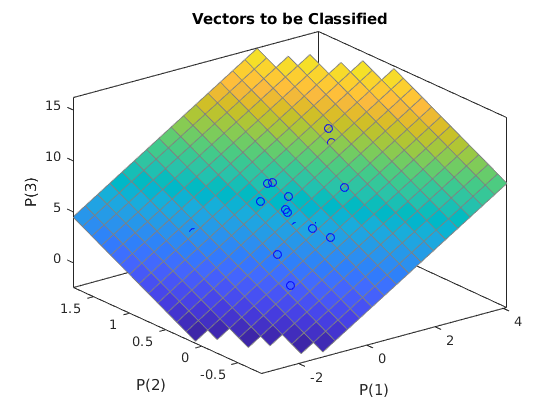

hiper_plot(nets{3}, X_train, y_train);

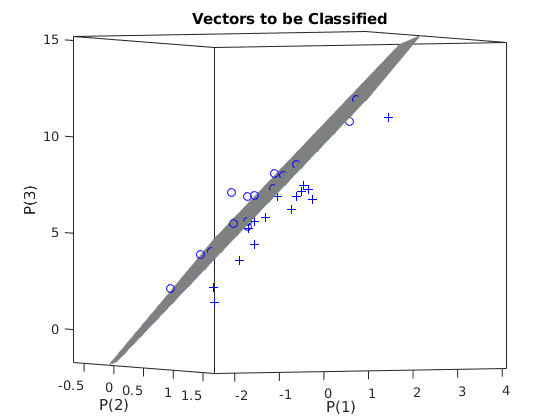

hiper_plot(nets{4}, X_train, y_train);

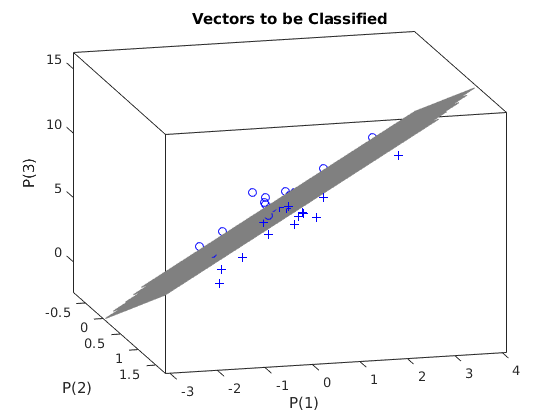

hiper_plot(nets{5}, X_train, y_train);

[nets{1}.IW{1,1}]

ans =   128.6518  227.5013  -59.2441


Niektóre trenowania zakończyły się przed 1000cznym treningiem, gdyż wylosowane wagi były bliżej tych, które spełniały założenia sieci, tj próg dla funkcji błędu, po którym sieć neuronowa kończy trenowanie został przekroczony.

weights = [
    nets{1}.IW{1,1}
    nets{2}.IW{1,1}
    nets{3}.IW{1,1}
    nets{4}.IW{1,1}
    nets{5}.IW{1,1}
]

weights =   128.6518  227.5013  -59.2441
   78.4501  118.2841  -33.8451
  140.0372  267.4454  -54.8876
   94.9324  159.9958  -52.7434
  100.7520  140.3880  -42.0937


accs = zeros(5,1)

accs =      0
     0
     0
     0
     0


for i = 1:5
    accs(i) = accuracy(nets{i}, X_train, y_train);
end

acc = 0.8667

acc = 0.8667

acc = 0.9000

acc = 0.8000

acc = 1

accs

accs =     0.8667
    0.8667
    0.9000
    0.8000
    1.0000


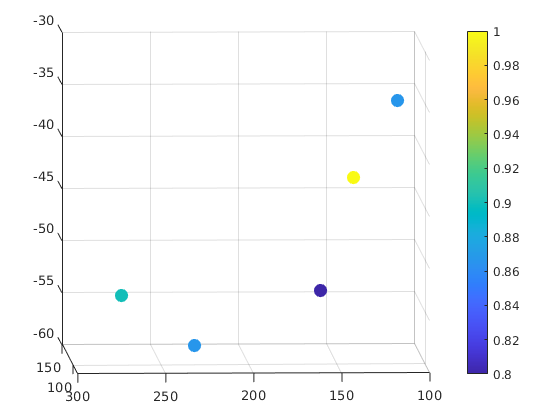

scatter3(weights(:,1),weights(:,2),weights(:,3), 100, accs, 'filled')
colorbar